# Dependencies

## Setup

Only when recomputing data extracted from apps, the following variables need to be set. Elaborating already extracted data available in the data2.mat file does not require this setup.

Run data-extracting code ONLY after running data-extracting code in selection.mlx and languages.mlx, as it is needed to to clone the app repositories and obtain the number of code lines.

Data-extracting code is commented not to disrupt the data-elaborating workflow.

In order for the data extracting code to work, it is necessary to setup the $PATH environment variable and Ruby environment version to execute terminal commands.

path = '$PATH';
rbenvVersion = "3.0.0";

Moreover, the location of the clones directory must be set:

clonesDir = '.';

Data collection for dependencies is all about gathering dependency sources from the specification files of each dependency manager: CocoaPods, Carthage and SwiftPM.

The following code gathers dependency sources for each commit of each app.

load ../../data/data2.mat data

Before looking for UI specification files in repositories the code temporarily removes the `Pods`, `Carthage` and `.build` directories, where resolved dependency files are usually located, thus avoiding to count dependencies of dependencies.

- Carthage: the following code makes use of the `CarthageAnalyzer` command-line tool that I developed. After invoking it with the location of a `Cartfile`, the tool returns a JSON containing a list with the sources of the dependencies. The code stores it in the `dependencies` struct of each commit, at the `carthage` field.

- CocoaPods: the following code obtains the list of CocoaPods dependency names contained in `Podfile` files. To do so, it uses the command-line tool `pod ipc podfile-json` to generate a JSON of the `Podfile`. It then parses the JSON and stores the dependency names in the `dependencies` struct of each commit, at the `cocoapods` field.

- SwiftPM: the following code extracts the names, locations and versions of SwiftPM dependencies from the `Package.resolved` JSON file that some repositories have. It then stores them in the `dependencies` struct of each commit, at the SwiftPM field.

% for k=1:size(data)
%     cd(clonesDir)
%     for vc=1:size(data{k, 10})
%         cd(clonesDir)
%         cd(data{k, 8});
%         system("git checkout --force " +  data{k, 10}(vc).tag, "PATH", path, "RBENV_VERSION", rbenvVersion);
% 
%         system("find . -name Pods -exec rm -rf {} \;", "PATH", path, "RBENV_VERSION", rbenvVersion);
%         system("find . -name Carthage -exec rm -rf {} \;", "PATH", path, "RBENV_VERSION", rbenvVersion);
%         system("find . -name .build -exec rm -rf {} \;", "PATH", path, "RBENV_VERSION", rbenvVersion);
%         
%         % Carthage: Cartfile
%         cartfile = dir("**/Cartfile");
%         
%         if ~isempty(cartfile)
% 
%             system("CarthageAnalyzer " + fullfile(cartfile(1).folder, "Cartfile") + " > " + clonesDir + "/cartfile.json", "PATH", path, "RBENV_VERSION", rbenvVersion);
%             cd(clonesDir)
%             str = fileread("cartfile.json");
%             error = false;
% 
%             try
%                 cart = jsondecode(str);
%             catch
%                 "Error decoding JSON"
%                 data{k, 10}(vc).dependencies.carthage = [];
%                 error = true;
%             end
% 
%             if not(error)
%                 cartList = strings;
%                 for t=1:size(cart)
%                     cartList(end + 1, 1) = convertCharsToStrings(cart(t).name);
%                 end
%                 cartList = cartList(2:end, 1);
%                 data{k, 10}(vc).dependencies.carthage = cartList;
%             end
%         end
%         
%         % Cocoapods: Podfile
% 
%         cd(clonesDir)
%         cd(data{k, 8});
%         podfile = dir("**/Podfile");
% 
%         if ~isempty(podfile)
%             cd(fullfile(podfile(1).folder));
% 
%             system("pod ipc podfile-json Podfile > " + clonesDir + "/podfile.json", "PATH", path, "RBENV_VERSION", rbenvVersion);
%             cd(clonesDir)
%             str = fileread("podfile.json");
%             error = false;
% 
%             try
%                 pods = jsondecode(str);
%             catch
%                 "Error decoding JSON"
%                 data{k, 10}(vc).dependencies.cocoapods = [];
%                 error = true;
%             end
%             
%             if not(error)
%                 podList = strings;
%                 for t=1:size(pods.target_definitions)
%                     if isfield(pods.target_definitions(t), "dependencies")
%                         for s=1:size(pods.target_definitions(t).dependencies)
%                             try
%                                 if isstruct(pods.target_definitions(t).dependencies{s,1})
%                                     var = fieldnames(pods.target_definitions(t).dependencies{s,1});
%                                 else 
%                                     var = pods.target_definitions(t).dependencies(s);
%                                 end
%                                 podList(end + 1, 1) = convertCharsToStrings(var{1});
%                             catch
%                                 if isstruct(pods.target_definitions(t).dependencies)
%                                     var = fieldnames(pods.target_definitions(t).dependencies);
%                                     var = var(1);
%                                 else 
%                                     var = pods.target_definitions(t).dependencies(s);
%                                 end
%                                 podList(end + 1, 1) = convertCharsToStrings(var{1});
%                             end
%                         end
%                     end
%                     if isfield(pods.target_definitions(t), "children")
%                         for q=1:size(pods.target_definitions(t).children)
%                             if iscell(pods.target_definitions(t).children)
%                                 if (not(isfield(pods.target_definitions(t).children{q, 1}, "platform")) || contains(fieldnames(pods.target_definitions(t).children{q,1}.platform), "ios")) && isfield(pods.target_definitions(t).children{q, 1}, "dependencies")
%                                     for s=1:size(pods.target_definitions(t).children{q, 1}.dependencies)
%                                         try
%                                             if isstruct(pods.target_definitions(t).children{q, 1}.dependencies{s,1})
%                                                 var = fieldnames(pods.target_definitions(t).children{q, 1}.dependencies{s,1});
%                                             else
%                                                 var = pods.target_definitions(t).children{q, 1}.dependencies{s, 1};
%                                             end
%                                             podList(end + 1, 1) = convertCharsToStrings(var);
%                                         catch
%                                             if isstruct(pods.target_definitions(t).children{q, 1}.dependencies)
%                                                 var = fieldnames(pods.target_definitions(t).children{q, 1}.dependencies);
%                                                 var = var(1);
%                                             else
%                                                 var = pods.target_definitions(t).children{q, 1}.dependencies;
%                                             end
%                                             podList(end + 1, 1) = convertCharsToStrings(var);
%                                         end
%                                     end
%                                 end
%                             elseif isstruct(pods.target_definitions(t).children)
%                                 if (not(isfield(pods.target_definitions(t).children(q), "platform")) || contains(fieldnames(pods.target_definitions(t).children(q).platform), "ios")) && isfield(pods.target_definitions(t).children(q), "dependencies")
%                                     for s=1:size(pods.target_definitions(t).children(q).dependencies)
%                                         try
%                                             if isstruct(pods.target_definitions(t).children(q).dependencies{s, 1})
%                                                 var = fieldnames(pods.target_definitions(t).children(q).dependencies{s, 1});
%                                             else 
%                                                 var = pods.target_definitions(t).children(q).dependencies{s, 1};
%                                             end
%                                             podList(end + 1, 1) = convertCharsToStrings(var);
%                                         catch
%                                             if isstruct(pods.target_definitions(t).children(q).dependencies)
%                                                 var = fieldnames(pods.target_definitions(t).children(q).dependencies);
%                                             else 
%                                                 var = pods.target_definitions(t).children(q).dependencies{s, 1};
%                                             end
%                                             podList(end + 1, 1) = convertCharsToStrings(var);
%                                         end
%                                     end
%                                 end
%                             end
%                         end
%                     end
%                 end
%     
%                 podList = unique(podList(2:end, 1));
%                 data{k, 10}(vc).dependencies.cocoapods = podList;
%             end
%         end
% 
%         % Swift Package Manager: Package.resolved
%         
%         cd(clonesDir)
%         cd(data{k, 8});
%         packageSwiftFile = dir("**/Package.resolved");
% 
%         if ~isempty(packageSwiftFile)
%             try
%                 file = fileread(fullfile(packageSwiftFile(1).folder, "/Package.resolved"));
%                 dependencies = jsondecode(file);
%             
%                 if dependencies.version == 2
%                     for j=1:size(dependencies.pins)
%                         try
%                             data{k, 10}(vc).dependencies.SwiftPM(j).name = dependencies.pins(j).identity;
%                         catch
%                         end
%                         try
%                             data{k, 10}(vc).dependencies.SwiftPM(j).location = dependencies.pins(j).location;
%                         catch
%                         end
%                         try
%                             data{k, 10}(vc).dependencies.SwiftPM(j).version = dependencies.pins(j).state.version;
%                         catch
%                         end
%                     end
%                 elseif dependencies.version == 1
%                     for j=1:size(dependencies.object.pins)
%                         try
%                             data{k, 10}(vc).dependencies.SwiftPM(j).name = dependencies.object.pins(j).package;
%                         catch
%                         end
%                         try
%                             data{k, 10}(vc).dependencies.SwiftPM(j).location = dependencies.object.pins(j).repositoryURL;
%                         catch
%                         end
%                         try
%                             data{k, 10}(vc).dependencies.SwiftPM(j).version = dependencies.object.pins(j).state.version;
%                         catch
%                         end
%                     end
%                 end
%             catch
%                 "ignored Package.resolved file"
%             end
%         end
%         "analyzed commit "+ vc + " out of " + length(data{k, 10}) + " of app " + k
%     end
% end

Since many repositories do not have a `Package.resolved` file, as it is a log file, the following code integrates them with the names, locations and versions available in the `project.pbxproj `project file contained in the main `.xcodeproj `package. The code performs a syntactical search for the values. The results are then stored in the `dependencies` struct of each commit, at the SwiftPM field, integrating the data obtained from `Package.resolved` files, if already available.

% for k=1:size(data)
%     cd(clonesDir)
%     for vc = 1:size(data{k, 10})
%         cd(clonesDir)
%         cd(data{k, 8});
%         system("git checkout --force " +  data{k, 10}(vc).tag, "PATH", path, "RBENV_VERSION", rbenvVersion);
%         
%         for j=1:length(data{k, 11})
%             if not(isempty(data{k, 12}))
%                 system(data{k, 12}, "PATH", path, "RBENV_VERSION", rbenvVersion);
%             end
%             if data{k, 11}(j) ~= "NO"
%                 cd(clonesDir)
%                 cd(data{k, 8});
%                 
%                 if isfolder(data{k, 11}(j)) && isfile(fullfile(data{k, 11}(j), "/project.pbxproj"))
%                     cd(data{k, 11}(j))
% 
%                     str = fileread(fullfile(data{k, 11}(j), "/project.pbxproj"));
% 
%                     str1 = extractBetween(str, "/* Begin XCRemoteSwiftPackageReference section */", "/* End XCRemoteSwiftPackageReference section */");
%                     str2 = extractBetween(str1, "/* XCRemoteSwiftPackageReference """, "};");
%                     names = extractBefore(str2, """");
%                     urls = extractBetween(str2, "repositoryURL = """, """");
% 
%                     if ~isempty(str2)
%                         if not(isfield(data{k, 10}(vc), "dependencies") && isfield(data{k, 10}(vc).dependencies, "SwiftPM"))
%                             for t = 1:length(str2)
%                                 data{k, 10}(vc).dependencies.SwiftPM(t).name = names{t, 1};
%                                 data{k, 10}(vc).dependencies.SwiftPM(t).location = urls{t, 1};
%                                 data{k, 10}(vc).dependencies.SwiftPM(t).version = [];
%                                 "added new, missing resolved file"
%                             end
%                         else
%                             for t = 1:length(str2)
%                                 if not(any(convertCharsToStrings(urls{t, 1}) == [convertCharsToStrings({data{k, 10}(vc).dependencies.SwiftPM.location})]))
%                                     data{k, 10}(vc).dependencies.SwiftPM(end+1).name = names{t, 1};
%                                     data{k, 10}(vc).dependencies.SwiftPM(end).location = urls{t, 1};
%                                     data{k, 10}(vc).dependencies.SwiftPM(end).version = [];
%                                      "added new, not present"
%                                 else
%                                     "already present"
%                                 end
%                             end
%                         end
%                   
%                     else
%                         "no dependencies found"
%                     end
%                     
%                     "analyzed commit "+ vc + " out of " + length(data{k, 10}) + " of app " + k
%                     break
%                 elseif j == length(data{k, 11})
%                         "ignoring commit " + vc + " of app " + k
%                 end
%             end
%         end
%     end
% end

## Dependency managers

The following code analyses which dependency managers are adopted in the latest commit of each app, returning three arrays containing the numbers of the apps adopting a specific method.

carthage = zeros(length(data), 1);
swiftPM = zeros(length(data), 1);
cocoapods = zeros(length(data), 1);
carthageT = [];
swiftPMT = [];
cocoapodsT = [];

for vc = 1:size(data)
    hasCarthage = false;
    hasSwiftPM = false;
    hasCocoaPods = false;

    if isfield(data{vc, 10}(end), "dependencies")
        if (isfield(data{vc,10}(end).dependencies, "carthage") && not(isstruct(data{vc,10}(end).dependencies.carthage)))
            hasCarthage = true;
            carthage(vc) = length(data{vc,10}(end).dependencies.carthage);
            carthageT(end+1, 1) = vc;
        end
        
        if (isfield(data{vc,10}(end).dependencies, "SwiftPM"))
            hasSwiftPM = true;
            swiftPM(vc) = length(data{vc,10}(end).dependencies.SwiftPM);
            swiftPMT(end+1, 1) = vc;
        end
        
        if (isfield(data{vc,10}(end).dependencies, "cocoapods") && not(isstruct(data{vc,10}(end).dependencies.cocoapods)))
            hasCocoaPods = true;
            cocoapods(vc) = length(data{vc,10}(end).dependencies.cocoapods);
            cocoapodsT(end+1, 1) = vc;
        end
    end
end

carthageT'

ans =      5    10    23    25    35    37    44    58    59    67    91   105   107   124


swiftPMT'

ans =      2     5     6     8     9    13    14    15    16    18    21    22    23    24    25    26    28    29    30    31    32    34    36    38    39    40    43    46    47    48    49    50    51    52    53    54    55    57    59    60    66    68    70    71    72    74    76    77    78    79


cocoapodsT'

ans =      3     4     8     9    11    12    14    17    18    19    20    21    24    27    33    35    43    45    47    49    50    52    54    61    62    63    64    65    73    74    75    80    82    83    84    88    90    91    92    94    97   100   101   102   104   110   111   115   116   119


The following code generates a plot showing the number of apps using a particular dependecy manager over time.

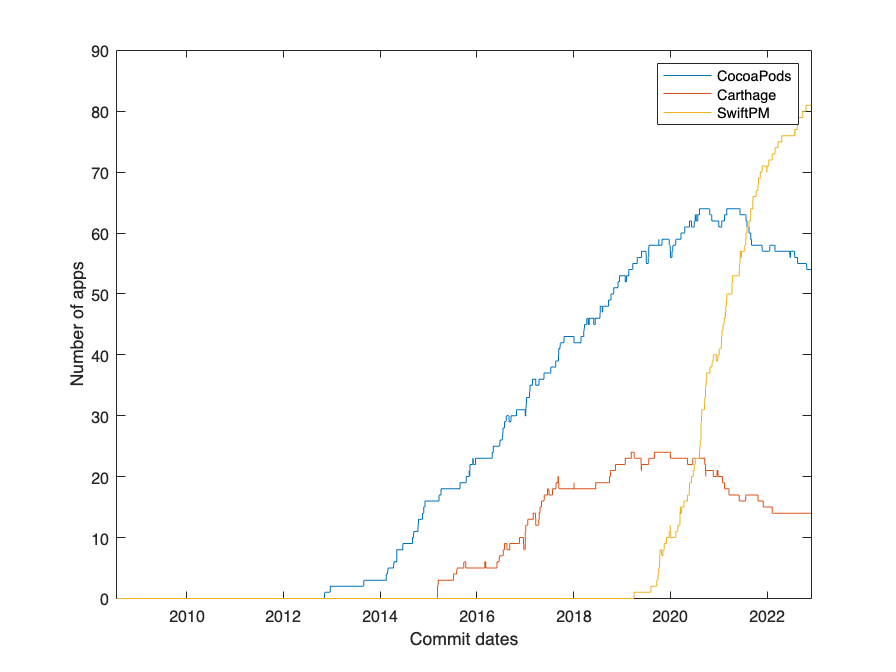

%% Plot package managers adoption - absolute

cocoapodsFix = [];
carthageFix = [];
swiftPMFix = [];
datesFix = NaT;

for vc = 1:size(data)
    dates = NaT;
    carthage = [];
    swiftPM = [];
    cocoapods = [];

    for j = 1:length(data{vc, 10})
        dates(j) = data{vc,10}(j).dateTime;
        if isfield(data{vc, 10}(j), "dependencies")
            if (isfield(data{vc,10}(j).dependencies, "carthage") && not(isstruct(data{vc,10}(j).dependencies.carthage)))
                carthage(j) = 1;
            else
                carthage(j) = 0;
            end
            
            if (isfield(data{vc,10}(j).dependencies, "SwiftPM"))
                swiftPM(j) = 1;
            else
                swiftPM(j) = 0;
            end
            
            if (isfield(data{vc,10}(j).dependencies, "cocoapods") && not(isstruct(data{vc,10}(j).dependencies.cocoapods)))
                cocoapods(j) = 1;
            else
                cocoapods(j) = 0;
            end
        else
            carthage(j) = 0;
            swiftPM(j) = 0;
            cocoapods(j) = 0;
        end
    end

    cocoapods = cocoapods(1:end);
    swiftPM = swiftPM(1:end);
    carthage = carthage(1:end);

    an = cocoapods;
    for i=2:length(cocoapods)
        an(i) = cocoapods(i) - cocoapods(i-1);
    end

    bn = swiftPM;
    for i=2:length(swiftPM)
        bn(i) = swiftPM(i) - swiftPM(i-1);
    end

    cn = carthage;
    for i=2:length(carthage)
        cn(i) = carthage(i) - carthage(i-1);
    end

    cocoapodsFix = [cocoapodsFix; an'];
    carthageFix = [carthageFix; cn'];
    swiftPMFix = [swiftPMFix; bn'];
    datesFix = [datesFix, dates(1:end)];
end

datesFix = datesFix';
datesFix = datesFix(2:end);

[datesFix, idx] = sort(datesFix, 'ascend');
cocoapodsFix = cocoapodsFix(idx, :);
carthageFix = carthageFix(idx, :);
swiftPMFix = swiftPMFix(idx, :);

cocoapodsFix = cumsum(cocoapodsFix);
carthageFix = cumsum(carthageFix);
swiftPMFix = cumsum(swiftPMFix);

figure;
plot(datesFix, cocoapodsFix);
hold on;
plot(datesFix, carthageFix);
hold on;
plot(datesFix, swiftPMFix);
xlim([datesFix(1) datesFix(end)])
hold off;
legend("CocoaPods", "Carthage", "SwiftPM");
xlabel('Commit dates') 
ylabel('Number of apps')

The following code generates a plot showing the number of dependencies per app over time grouped by dependecy manager.

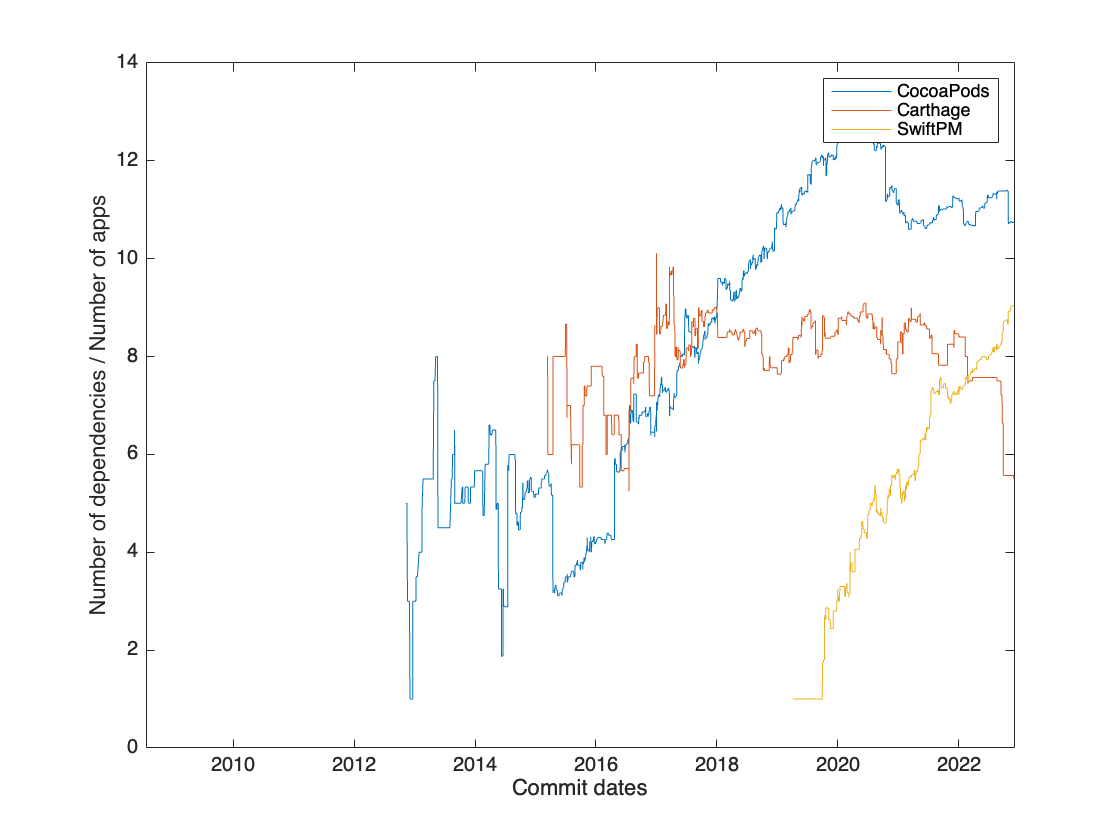

%% Plot package managers adoption - relative

cocoapodsFix1 = [];
carthageFix1 = [];
swiftPMFix1 = [];
datesFix = NaT;

for vc = 1:size(data)
    dates = NaT;
    carthage = [];
    swiftPM = [];
    cocoapods = [];

    for j = 1:length(data{vc, 10})
        dates(j) = data{vc,10}(j).dateTime;
        if isfield(data{vc, 10}(j), "dependencies")
            if (isfield(data{vc,10}(j).dependencies, "carthage") && not(isstruct(data{vc,10}(j).dependencies.carthage)))
                carthage(j) = length(data{vc,10}(j).dependencies.carthage); 
            else
                carthage(j) = 0;
            end
            
            if (isfield(data{vc,10}(j).dependencies, "SwiftPM"))
                swiftPM(j) = length(data{vc,10}(j).dependencies.SwiftPM);
            else
                swiftPM(j) = 0;
            end
            
            if (isfield(data{vc,10}(j).dependencies, "cocoapods") && not(isstruct(data{vc,10}(j).dependencies.cocoapods)))
                cocoapods(j) = length(data{vc,10}(j).dependencies.cocoapods);
            else
                cocoapods(j) = 0;
            end
        else
            carthage(j) = 0;
            swiftPM(j) = 0;
            cocoapods(j) = 0;
        end
    end

    cocoapods = cocoapods(1:end);
    swiftPM = swiftPM(1:end);
    carthage = carthage(1:end);

    an = cocoapods;
    for i=2:length(cocoapods)
        an(i) = cocoapods(i) - cocoapods(i-1);
    end

    bn = swiftPM;
    for i=2:length(swiftPM)
        bn(i) = swiftPM(i) - swiftPM(i-1);
    end

    cn = carthage;
    for i=2:length(carthage)
        cn(i) = carthage(i) - carthage(i-1);
    end

    cocoapodsFix1 = [cocoapodsFix1; an'];
    carthageFix1 = [carthageFix1; cn'];
    swiftPMFix1 = [swiftPMFix1; bn'];
    datesFix = [datesFix, dates(1:end)];
end

datesFix = datesFix';
datesFix = datesFix(2:end);

[datesFix, idx] = sort(datesFix, 'ascend');
cocoapodsFix1 = cocoapodsFix1(idx, :);
carthageFix1 = carthageFix1(idx, :);
swiftPMFix1 = swiftPMFix1(idx, :);

cocoapodsFix1 = cumsum(cocoapodsFix1);
carthageFix1 = cumsum(carthageFix1);
swiftPMFix1 = cumsum(swiftPMFix1);

figure;
plot(datesFix, cocoapodsFix1 ./ cocoapodsFix);
hold on;
plot(datesFix, carthageFix1 ./ carthageFix);
hold on;
plot(datesFix, swiftPMFix1 ./ swiftPMFix);
xlim([datesFix(1) datesFix(end)])
hold off;
legend("CocoaPods", "Carthage", "SwiftPM");
xlabel('Commit dates')
ylabel('Number of dependencies / Number of apps')

## Dimensions/Dependencies Relation

The following code stores, in a `codeComplexity` struct field for each commit, the sum of Objective-C and Swift lines of code, necessary for the following step.

for i=1:length(data)
    for j=1:length(data{i, 10})
        data{i, 10}(j).codeComplexity = data{i, 10}(j).ObjcSwiftCloc.Swift.size + data{i, 10}(j).ObjcSwiftCloc.Objective_C.size;
    end
end

The following code generates a scatter plot to evaluate the relation between code complexity and number of adopted dependencies in apps.

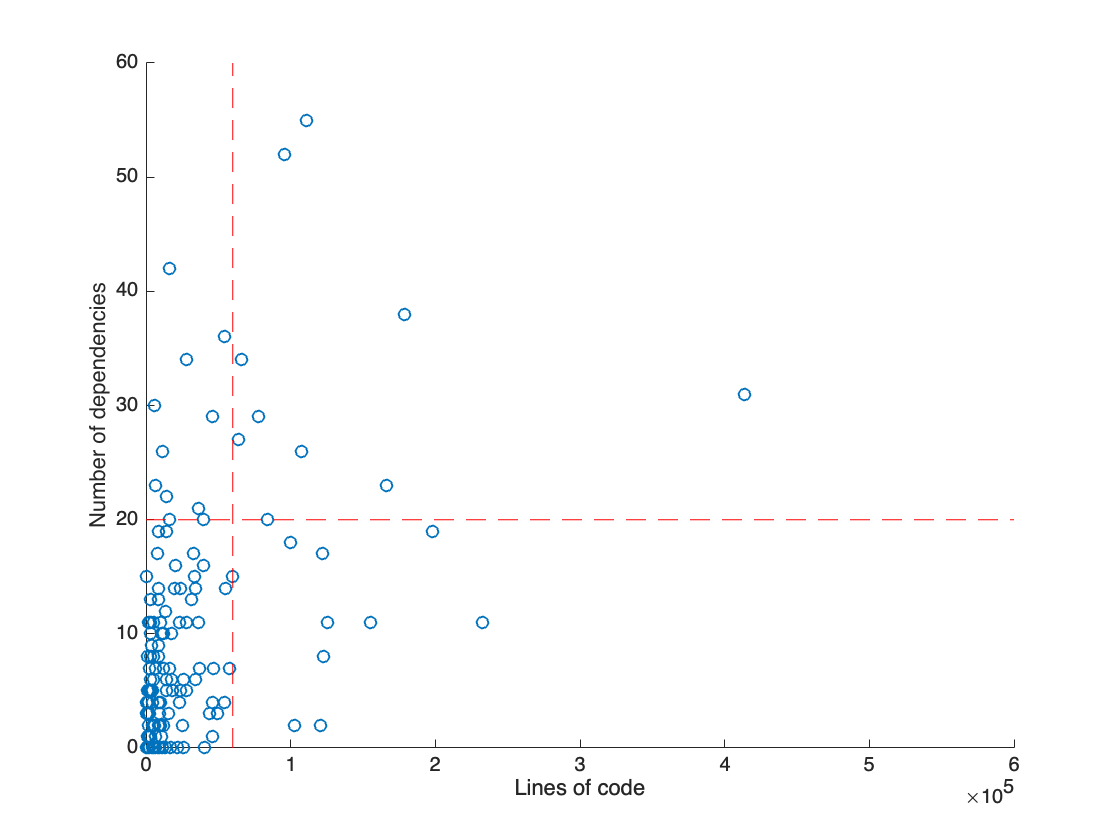

carthage = zeros(length(data), 1);
swiftPM = zeros(length(data), 1);
cocoapods = zeros(length(data), 1);
dependencies = zeros(length(data), 1);

for vc = 1:size(data)
    if isfield(data{vc, 10}(end), "dependencies")
        if (isfield(data{vc,10}(end).dependencies, "carthage") && not(isstruct(data{vc,10}(end).dependencies.carthage)))
            carthage(vc) = length(data{vc,10}(end).dependencies.carthage);
        end
        
        if (isfield(data{vc,10}(end).dependencies, "SwiftPM"))
            swiftPM(vc) = length(data{vc,10}(end).dependencies.SwiftPM);
        end
        
        if (isfield(data{vc,10}(end).dependencies, "cocoapods") && not(isstruct(data{vc,10}(end).dependencies.cocoapods)))
            cocoapods(vc) = length(data{vc,10}(end).dependencies.cocoapods);
        end
    end
end

dependencies = carthage + swiftPM + cocoapods;

sizes = zeros(length(data), 1);
for i=1:size(data)
    sizes(i) = data{i, 10}(end).codeComplexity;
end

insideArea = sum((sizes <= 60000) .* (dependencies > 20));

figure;
scatter(sizes, dependencies, 'LineWidth', 1);
hold on;
line([60000, 60000], [0, 60], 'LineStyle', "--", 'Color', 'r');
line([0, 600000], [20, 20], 'LineStyle', "--", 'Color', 'r');
xlabel('Lines of code') 
ylabel('Number of dependencies') 

## Most used dependencies

The following code normalises data coming from the three different dependency managers and computes a list of the most used dependencies.

- Carthage: dependency sources are stripped of the `github` prefix, leaving them with just the `repo_owner/repo_name` field. Then, they are lowercased and punctuation is removed.

- CocoaPods: dependency names are resolved using the `pod search` terminal command, returning the source of the repository containing the dependency. Manual cleaning and resolution has been performed. Dependency sources are then reduced to have just the `repo_owner/repo_name` field. Then, they are lowercased and punctuation is removed.

- SwiftPM: dependency sources are reduced to have just the `repo_owner/repo_name` field. Then, they are lowercased and punctuation is removed.

Retrieved data is then put together and, obtaining a `name: occurrencies` entry for each dependency.

% carthage = zeros(length(data), 1);
% swiftPM = zeros(length(data), 1);
% cocoapods = zeros(length(data), 1);
% 
% cart1 = strings;
% swiftPM1 = strings;
% pods1 = strings;
% 
% 
% for vc = 1:size(data)
%     if isfield(data{vc, 10}(end), "dependencies")
%         if (isfield(data{vc,10}(end).dependencies, "carthage") && not(isstruct(data{vc,10}(end).dependencies.carthage)))
%             cart1 = [cart1; unique(data{vc,10}(end).dependencies.carthage)];
%         end
%         
%         if (isfield(data{vc,10}(end).dependencies, "SwiftPM"))
%             swiftPM1 = [swiftPM1; unique(convertCharsToStrings({data{vc,10}(end).dependencies.SwiftPM.location}))'];
%         end
%         
%         if (isfield(data{vc,10}(end).dependencies, "cocoapods") && not(isstruct(data{vc,10}(end).dependencies.cocoapods)))
%             pods1 = [pods1; unique(data{vc,10}(end).dependencies.cocoapods)];
%         end
%     end
% end
% 
% 
% for i=2:length(cart1)
%     cart1(i, 1) = extractBetween(cart1(i, 1), '"', '"');
% end
% 
% for i=1:length(pods1)
%     [s, output] = system('pod search "' + pods1(i) + '" --ios --no-pager | grep " - Source:" -m 1', "PATH", path, "RBENV_VERSION", rbenvVersion);
%     pods1(i, 3) = strtrim(extractAfter(output, "- Source:"));
%     "completed " + i + " out of " + length(pods1)
% end
% 
% for i=1:length(pods1)
%     if contains(pods1(i, 3), "github.com/")
%         pods1(i, 2) = erase(extractAfter(pods1(i, 3), "github.com/"), ".git");
%     else
%         pods1(i, 2) = pods1(i, 3);
%     end
% end
% 
% for i=1:length(swiftPM1)
%     if contains(swiftPM1(i, 1), "github.com/")
%         swiftPM1(i, 2) = erase(extractAfter(swiftPM1(i, 1), "github.com/"), ".git");
%     else
%         swiftPM1(i, 2) = swiftPM1(i, 1);
%     end
% end
% 
% [p1, p2] = groupcounts([lower(erasePunctuation(pods1(2:end, 2))); lower(erasePunctuation(swiftPM1(2:end, 2))); lower(erasePunctuation(cart1(2:end, 1)))]);
% p = [num2cell(p1), cellstr(p2)];
% p = sortrows(p, 1, 'descend'); % result is here

The final list is available at the following variable:

load ../../data/depStats.mat p
p

p = 715×2 cell array
    {[20]}    {'firebasefirebaseiossdk'                                }
    {[19]}    {'onevcatkingfisher'                                     }
    {[15]}    {'alamofirealamofire'                                    }
    {[15]}    {'sdwebimagesdwebimage'                                  }
    {[15]}    {'snapkitsnapkit'                                        }
    {[13]}    {'airbnblottieios'                                       }
    {[12]}    {'appleswiftlog'                                         }
    {[12]}    {'appleswiftprotobuf'                                    }
    {[10]}    {'bizz84swiftystorekit'                                  }
    {[10]}    {'danielgindicharts'                                     }
    {[10]}    {'getsentrysentrycocoa'                                  }
    {[10]}    {'realmswiftlintreleasesdownload0503portableswiftlintzip'}
    {[ 9]}    {'appleswiftcollections'                                 }
    {[ 9]}    {'cocoalumberjac